# Linear Control Design II - Group Work Problem Module 12 solution 

## Description

**Problems**

The assignment deals with the multi-variable controller design for the TITO (two-inputs two-outputs) model of the aircraft introduced in Group Work Module 9.

The state space representation of the model is


$$ \pmatrix
    { \dot{\beta}\cr
   \dot{r}\cr
   \dot{p}\cr
   \dot{\phi}}
 =    \left(\begin{array}{cccc} -0.0558 & -0.9968 & 0.0802 & 0.0415\\ 0.598 & -0.115 & -0.0318 & 0\\ -3.05 & 0.388 & -0.465 & 0\\ 0 & 0.0805 & 1.0 & 0 \end{array}\right)
 \pmatrix{
   \beta \cr
   r\cr
   p\cr
   \phi}
 
 +
\left(\begin{array}{cc} 0.00729 & 0.00001\\ -0.475 & 0.123\\ 0.153 & 1.063\\ 0 & 0 \end{array}\right)
 \pmatrix{
   \delta r\cr
   \delta a
  } \\
 \mathbf{y}=\pmatrix{
  0 \ 1 \ 0 \ 0\cr
  0 \ 0 \ 0 \ 1
 }
 \pmatrix{  \beta\cr
   r\cr
   p\cr
   \phi
  }$$


**Problem 1** 	Assess if the open loop system is controllable. Is the system stabilizable?.

**Solution****:**

**State controller for airplane model**

In this module a full state controller is designed for the linear model of the airplane. Furthermore, the effects of model changes into the controller performance are investigated**. **

The linear model of the airplane is given by


$$ \pmatrix
    { \dot{\beta}\cr
   \dot{r}\cr
   \dot{p}\cr
   \dot{\phi}}
 =    \left(\begin{array}{cccc} -0.0558 & -0.9968 & 0.0802 & 0.0415\\ 0.598 & -0.115 & -0.0318 & 0\\ -3.05 & 0.388 & -0.465 & 0\\ 0 & 0.0805 & 1.0 & 0 \end{array}\right)
 \pmatrix{
   \beta \cr
   r\cr
   p\cr
   \phi}
 
 +
\left(\begin{array}{cc} 0.00729 & 0.00001\\ -0.475 & 0.123\\ 0.153 & 1.063\\ 0 & 0 \end{array}\right)
 \pmatrix{
   \delta r\cr
   \delta a
  } \\
 \mathbf{y}=\pmatrix{
  0 \ 1 \ 0 \ 0\cr
  0 \ 0 \ 0 \ 1
 }
 \pmatrix{  \beta\cr
   r\cr
   p\cr
   \phi
  }$$


The first step in control design is to evaluate the controllability and stabilizability properties of the system at hand. If the system is not fully controllable i.e. the controllability matrix is not full row rank then to assess the stabilizability of the system becomes of paramount importance in order to solve the control problem. Remember that a system is said to be stabilizable if all uncontrollable states are stable.

First, using the controllability theorem CC2 we check for controllability, that is


$$\mathbf{M}_c=\pmatrix{\mathbf{B}  \ \mathbf{AB} \ \mathbf{A^2B} \ \mathbf{A^3B}}\\

\mathbf{M}_c=\left(\begin{array}{cccccccc} 0.00729 & 0.00001 & 0.48534 & -0.037354 & -0.098535 & 0.058581 & -0.40443 & 0.0049517\\ -0.475 & 0.123 & 0.054119 & -0.047942 & 0.29284 & -0.0026226 & -0.050301 & 0.025698\\ 0.153 & 1.063 & -0.27768 & -0.4466 & -1.3302 & 0.303 & 1.0327 & -0.32059\\ 0 & 0 & 0.11476 & 1.0729 & -0.27332 & -0.45046 & -1.3066 & 0.30279 \end{array}\right)$$


The controllability matrix $\mathbf{M}_c$ has full row rank; hence all states are controllable and there is no need to further investigate for stabilizability, since a controllable system is obviously stabilizable.

**Problem 2** A multi-variable full state feedback controller $\mathbf{u} = -\mathbf{K}\mathbf{x} + \mathbf{r}$ for the aircraft is to be designed. The continuous time closed-loop system's eigenvalues have to be placed at the following location in the left half plane


$$ \lambda=\left\{\begin{array}{l}
	  -0.5\\ -0.6\\ -0.5\pm 0.5\rm{j}
	 \end{array}
$$


Design a discrete time controller and use the sampling period ${0.1}$$s$. Find the gain matrix $\mathbf{K}$ for the controller by applying the Matlab function *place*. Check the position of the eigenvalues of the closed-loop system. Are the design requirements fulfilled?

**Solution****:**

**1.1 Continuous Time State Feedback Controller**

The design of the continuous time state feedback controller is done by pole placement through the MATLAB function `place`. Since the system at hand is TITO (two inputs - two outputs) the function `place` will assign both eigenvalues and eigenvectors, guaranteeing the orthogonality of the assigned eigenvectors. For the desired set of closed loop eigenvalues:


$$ \lambda=\left\{\begin{array}{l}
	  -0.5\\ -0.6\\ -0.5\pm 0.5\rm{j}
	 \end{array}
$$


the obtained continuous controller is:


$$ \mathbf{K}=\left(
  \begin{array}{cccc}
  -1.4256 & -1.7645 & -0.63117 & -0.36287\\
  -2.3647 & 0.11052 & 0.67682 & 031429
  \end{array}\right)$$


format short g
A=[-.0558 -.9968 .0802 .0415;
   .598 -.115 -.0318 0;
   -3.05 .388 -.4650 0;
   0 .0805 1 0];
B=[.0729  .0001;
   -4.75   1.23;
   1.53   10.63;
   0      0]/10;
C=[0 1 0 0;
   0 0 0 1];
D=[0 0;
   0 0];

%% controlability
Mc = [B A*B A^2*B A^3*B];
rank(Mc)

ans =      4


%%Continuous controller

pl = [-0.5 -0.6 -0.5+1i*0.5 -0.5-1i*0.5];
K = place(A,B,pl);
lambda = eig(A-B*K);

**1.2 Discrete Time State Feedback Controller**

The discrete time state feedback controller is design based on the discretized model, given by


$$\mathbf{F} = \exp(\mathbf{A}T) \\
	\mathbf{G} = \int_0^T{\exp(\mathbf{A}t)\mathbf{B}}\,\mathrm{d}t \\
	\mathbf{\lambda}_{\mathbf{F}} = \exp(\mathbf{\lambda}_{\mathbf{A}}T)$$


where $\mathbf{F}$ is the discrete time state matrix, $\mathbf{G}$ the discrete time input matrix, and $\mathbf{\lambda}_{\mathbf{F}}$ the discrete time eigenvalues. The function \texttt{place} is also used for the discrete time system, and the controller is obtained as follow:


$$ \mathbf{K}=\left(
  \begin{array}{cccc}
  -1.4184 & -1.6498 & -0.59416 & -0.34536\\
   -2.3737 & 0.24586 & 0.63373 & 0.29318
  \end{array}\right)$$


**Problem 3 ** Add the controller to the Simulink model and carry out a simulation with the function in the following Figure as reference signal for both inputs, but one at a time. Plot the states, outputs and control signals, i.e. the rudder angle and the aileron angle.

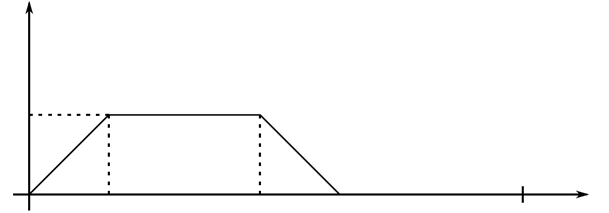

                                                                                             Figure 1: Reference signal for the closed-loop system.

**Solution****:**

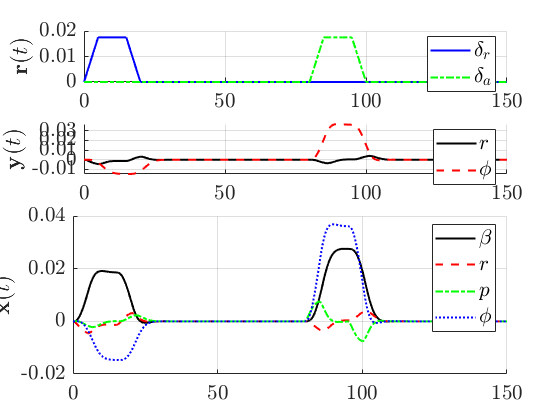

%%
%
% Generation of reference-signals
%
t=0:.1:150;
t1=0:.1:5;
r1=.0175*t1/5;
r3=.0175*(4-(t1+15)/5);
ra=[zeros(800,1)' r1 .0175*ones(99,1)' r3 zeros(1,500)];
r=[r1 .0175*ones(99,1)' r3 zeros(800,1)' zeros(1,500)];
inp = [t' r' ra'];
[ts,xs,ys] = sim('lat747mod10',150,[],inp);

%%%%%%%%%
%
% plotting the results
%
%%%%%%%%%
% continuous controller

figure, h1 = subplot(4,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h2 = subplot(4,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(ts,ys(:,1),'k',ts,ys(:,2),'--r','LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h3 = subplot(4,1,3:4); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(ts,xs(:,1),'k',ts,xs(:,2),'--r',ts,xs(:,3),'-.g',ts,xs(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

Figure 2: Simulation of the continuous time state feedback controller.

The fulfilment of the closed loop requirement (position of the eigenvalues) is checked by solving the closed loop eigenvalue problem $det(\mathbf{I}\lambda - \mathbf{A} + \mathbf{BK}) = 0$. Figure 2 illustrates the performance of the closed loop system in response to the reference signal.

**Simulink implementation and simulation**

To implement the discrete time controller together with the continuous time system in SIMULINK requires the inclusion of AD and DA converters, as shown in Figure 3. The simulation results of the sampled data system are shown in Figure 4. Comparing Figure 4 with Figure 2 it is worth noting that the discrete time controller ensures the same performance of the continuous time controller.

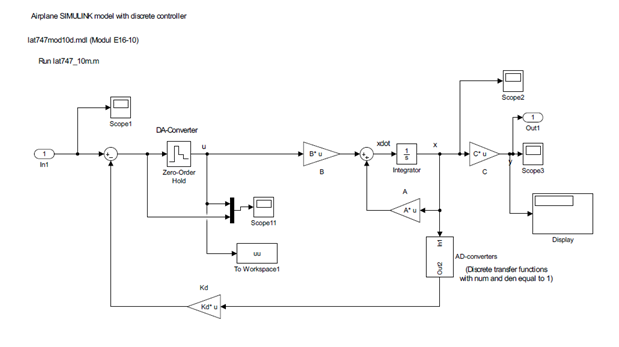

                                                                                                           Figure 3: SIMULINK block diagram with AD and DA converters included.

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Discrete Controller design
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ev=[-.5 -.6 -.5+1i*.5 -.5-1i*.5];
T=0.1;
[F,G]=c2d(A,B,T);
evd=exp(T*ev);
Kd=place(F,G,evd)

Kd =       -1.4184      -1.6498     -0.59416     -0.34536
      -2.3737      0.24586      0.63373      0.29318


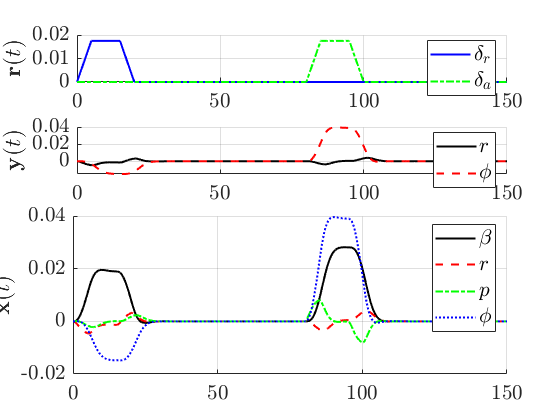

lambdaA = log(eig(F-G*Kd))/T;

[td,xd,yd] = sim('lat747mod10d',150,[],inp);

%%%%%%%%%
%
% plotting the results
%
%%%%%%%%%
% discrete model

figure, h4 = subplot(4,1,1); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h5 = subplot(4,1,2); set(h5,'FontName','times','FontSize',16)
hold on, grid on
plot(td,yd(:,1),'k',td,yd(:,2),'--r','LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h6 = subplot(4,1,3:4); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(td,xd(:,1),'k',td,xd(:,2),'--r',td,xd(:,3),'-.g',td,xd(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

Figure 4: Simulation of the sampled data system.

**Problem 4 ** Now suppose that the aircraft's rudder and aileron servos are slower than we thought. Add a $1 \ s$ time constant to each of the continuous control inputs and see what happens. How could the problem be solved?

**Solution****:**

**Actuators with Slower Dynamics**

 To illustrate how the performance of the controller depends on the systems it is design for, actuators with slower dynamics are included into the system. This is achieved by including two low pass filters (one for each input) with time constant of one second before the input matrix $\mathbf{B}$. Figure 5 clearly shows that the controller is affected by the slower dynamics of the actuators and, therefore, the performance shown in Figure 4 can no longer be guaranteed. Hence a new controller should be designed for this new system dynamics.

The design of a new controller passes through the expansion of the system dynamical model as mentioned in problem 1.


$$\mathbf{x} = \left[\matrix {\beta  \ r \ p \ \phi  \ z_1 \ z_2} \right]^T \\
\overline{\mathbf{A}} = \left[\begin{array}{cc} \mathbf{A} & \mathbf{B}\\ \mathbf{0_{2 \times 4}} & -\mathbf{I_{2}} \end{array}\right] \\
\overline{\mathbf{B}} = \left[\begin{array}{c} \mathbf{0_{4 \times 2}} \\ \mathbf{I_2} \end{array}\right] \\
\overline{\mathbf{C}} = \left[\begin{array}{cc} \mathbf{C} & \mathbf{0_{2 \times 2}} \end{array}\right]$$


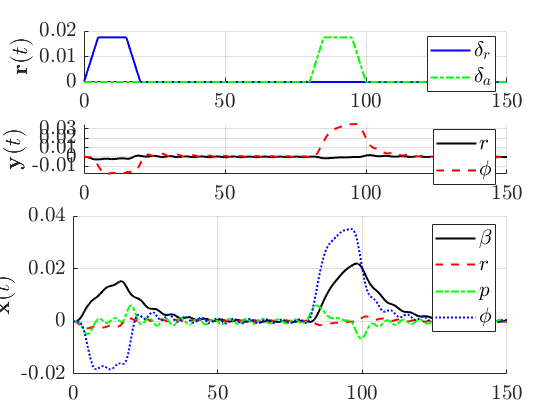

%% Model with added timeconstants

[tdn,xdn,ydn] = sim('lat747mod10dn',150,[],inp);

%%%%%%%%%
%
% plotting the results
%
%%%%%%%%%
% discrete model

figure, h7 = subplot(4,1,1); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(t,r,'b',t,ra,'-.g','LineWidth',1.5)
ylabel('$\mathbf{r}(t)$','FontName','times','FontSize',16,'interpreter','latex')
l = legend('$\delta_r$','$\delta_a$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h8 = subplot(4,1,2); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(tdn,ydn(:,1),'k',tdn,ydn(:,2),'--r','LineWidth',1.5)
ylabel('$\mathbf{y}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$r$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

h9 = subplot(4,1,3:4); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(tdn,xdn(:,1),'k',td,xdn(:,2),'--r',tdn,xdn(:,3),'-.g',tdn,xdn(:,4),':b','LineWidth',1.5)
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'interpreter','latex')
hold off
l = legend('$\beta$','$r$','$p$','$\phi$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'interpreter','latex')

Figure 5: Simulation of the discrete time controller on the system with slower actuators.

**Problem 5 **Find the stationary output $\mathbf{y}_0$ for the closed-loop system and for the constant reference inputs $\mathbf{r}(k)=\left[\matrix{0.1 \   0}\right]^\mathrm{T}$ and $\mathbf{r}(k)=\left[\matrix{0  \ 0.1}\right]^\mathrm{T}$. Does $y_0$ depend on the eigenvalue placement? (`Hint: For a stationary state the discrete state vector is constant, i.e.` $\mathbf{x}(k+1)=\mathbf{x}(k)$).

**Solution****:**

**Stationary States**

The following equations how  the stationary states depend on the controller. Since the controller is designed based on the desired closed loop eigenvalues, it is evident that also the stationary states are dependent on them.


$$\mathbf{x}(k+1) = \mathbf{x}(k) \Rightarrow \mathbf{x}_0 = (\mathbf{F} - \mathbf{GK})\mathbf{x}_0 + \mathbf{G}\mathbf{r}_0 \\
	(\mathbf{I} -\mathbf{F} + \mathbf{GK})\mathbf{x}_0 = \mathbf{G}\mathbf{r}_0 \\
	\mathbf{x}_0 = \mathbf{Q}^{-1}\mathbf{G}\mathbf{r}_0,  \mathbf{Q} = (\mathbf{I} -\mathbf{F} + \mathbf{GK}) \\
	\mathbf{y}_0 = \mathbf{C}\mathbf{x}_0 = \mathbf{C}\mathbf{Q}^{-1}\mathbf{G}\mathbf{r}_0$$


% Computation of stationary states x0 and outputs y0:
%
r0=[.1 0]';
x0=inv(eye(4,4)-F+G*Kd)*G*r0

x0 =        0.1082
   -0.0079812
   0.00064249
    -0.084668


y0=C*x0

y0 =    -0.0079812
    -0.084668



r0=[0 .1]';
x0=inv(eye(4,4)-F+G*Kd)*G*r0

x0 =       0.16043
    0.0025628
  -0.00020631
      0.22332


y0=C*x0

y0 =     0.0025628
      0.22332
